## Task 2

## a. Frequency domain degradation

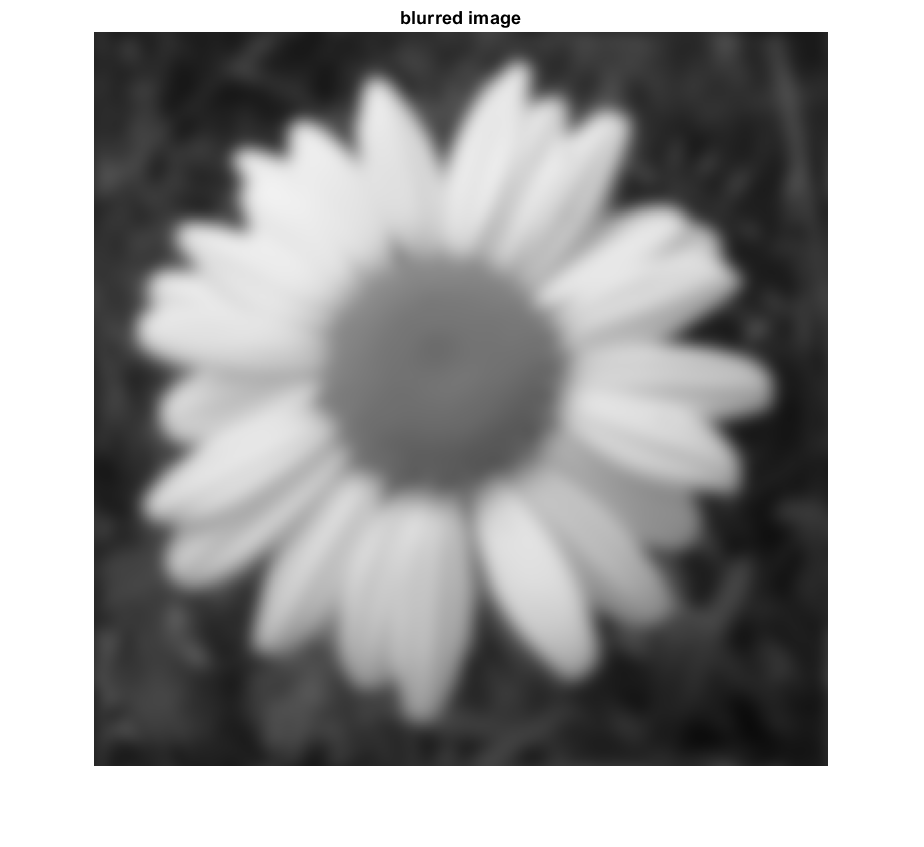

close all; clear; clc

% Read the image
img = imread('daisy.jpg');
img_values = double(rgb2gray(img));
[n1, n2] = size(img_values);

% Calculate the DFT of the image
f = fftshift(fft2(img_values));

% Get the degradation function
h1 = gaussian(0.0025, n1,n2);
h1(h1 == 0) = 0.001;

%Apply degradation
f1 = f .* h1;

% Find the inverse FT
restore_img = ifft2(f1);
blurred = abs(restore_img)/255;
figure; imshow(blurred); title('blurred image');


% Generate Gaussian noise


## b. Inverse filtering without noise

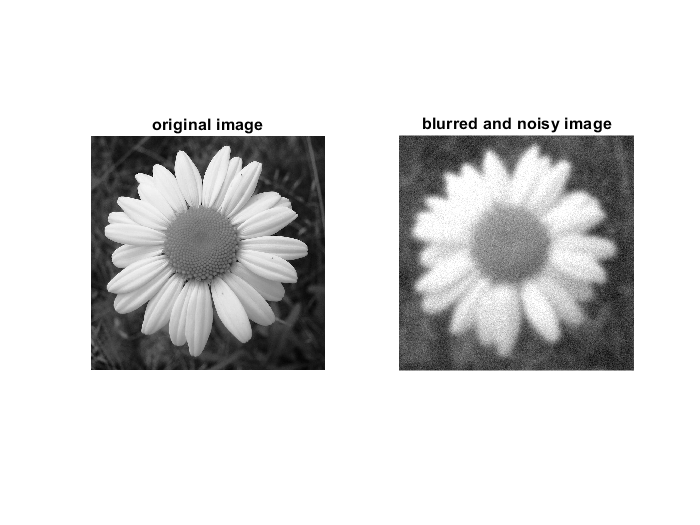

mu= 0.1;
sigma = 0.05;
noise = normrnd(mu,sigma,size(img_values));
noise(noise == 0) = 0.0001;

% Add noise to the spatial domain of the image
blurred_noisy_image = blurred + noise;

% Display the image
figure;
subplot(1,2,1); imshow(img_values/255); title('original image');
subplot(1,2,2);imshow(blurred_noisy_image); title('blurred and noisy image');

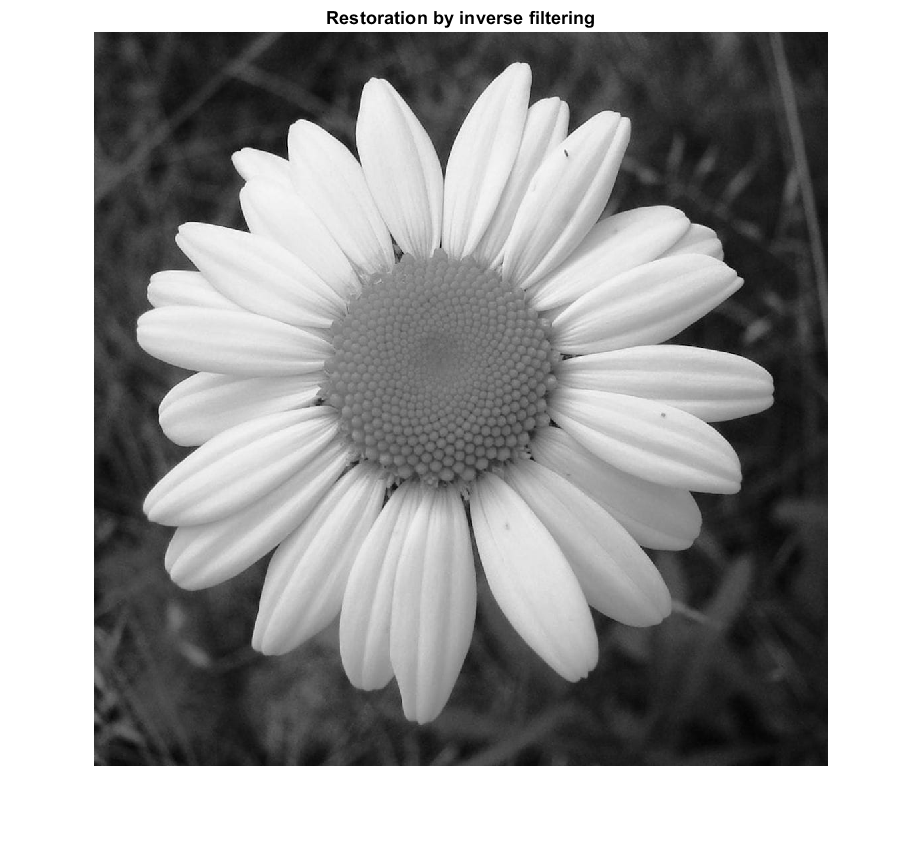

F = f1./h1;
F = ifft2(F);
figure;
imshow(abs(F)/255); title('Restoration by inverse filtering');

## c. Wiener filter

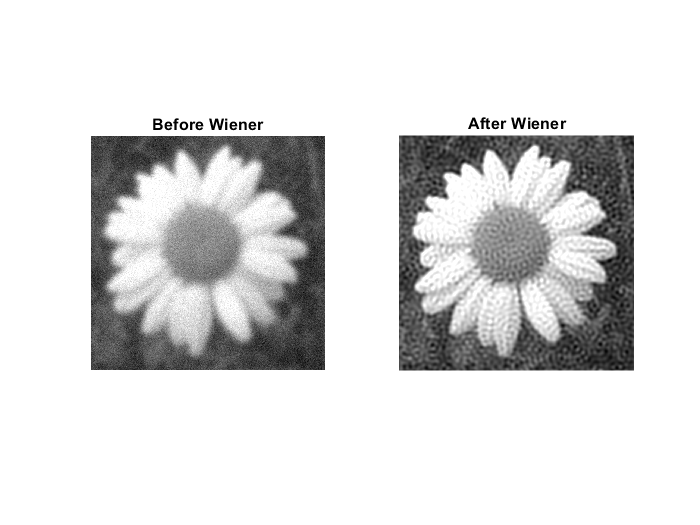



%Calculate |H(u,v)|^2
h2 = abs(h1).^2;
%Calculate Sn(u,V)
noise_freq = fftshift(fft2(noise));
sn = abs(noise_freq);
%Calculate Sf(u,v)
sf = abs(f);
wiener = (conj(h1)./(h2 + sn./sf));
blur_noise_freq = fftshift(fft2(blurred_noisy_image));
r1 = wiener .* blur_noise_freq;
re = ifft2(r1);
figure;
subplot(1,2,1);imshow(blurred_noisy_image); title('Before Wiener');
subplot(1,2,2);imshow(abs(re)); title('After Wiener');

### The function for the gaussian blur

function h = gaussian(k, n1, n2)
[k1, k2] = meshgrid(-n2/2+1:n2/2, -n1/2+1:n1/2);
d = (k1.^2 + k2.^2);
h = exp(-k  .* d );
end